L'immagine a colori color noisy.png presenta un fastidioso disturbo. Operando esclusivamente sulla componente di luminanza realizzate un �ltraggio nel dominio della frequenza allo scopo di ridurre quanto più possibile tale disturbo.

Per valutare la bontà dell'elaborazione calcolate il PSNR tra l'intensità dell'immagine �filtrata e quella dell'originale (contenuta nel �le color clear.jpg). Mostrate a video l'immagine originale, la rumorosa e la �filtrata (a colori).

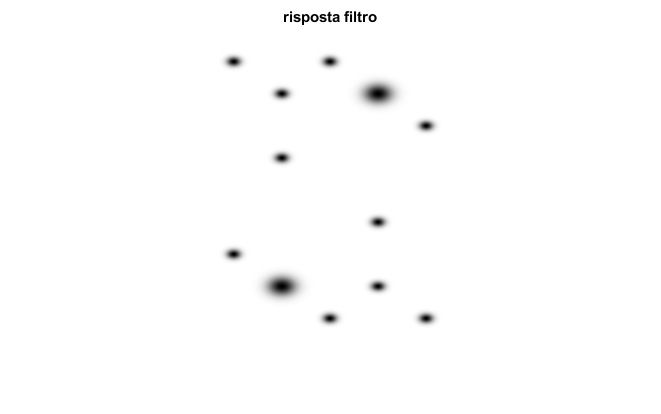

clear all; close all; clc;
x = imread('color_noisy.png');

% RGB to HSI
xhsi = rgb2hsi(x);
h = xhsi(:,:,1);
s = xhsi(:,:,2); 
i = xhsi(:,:,3);

% Definizione griglia
[M,N] = size(xhsi(:,:,3));
n = -1/2:1/N:1/2-1/N;
m = -1/2:1/M:1/2-1/M;
[l,k] = meshgrid(n,m);

% DFT componente luminanza
I = fftshift(fft2(i));

% Filtro
C = [-0.1 -0.1; 0.1 0.1; -0.3 0.1; 0.3 -0.1; -0.2 0.2; 0.2 -0.2; -0.3 -0.1; 0.3 0.1; -0.4 0; 0.4 0; -0.4 -0.2; 0.4 0.2]; % centri
sigma = [0.01 0.01 0.02 0.02 0.01 0.01 0.01 0.01 0.01 0.01 0.01 0.01]; 
H = ones(M,N);
for i=1:length(sigma)
    D = sqrt((l-C(i,2)).^2+(k-C(i,1)).^2);
    H = H - exp(-D.^2/(2*sigma(i)^2));
    % H = H - (1./(1+(D./sigma(i)).^2));  butterworth
end

figure; imshow(H); title('risposta filtro');

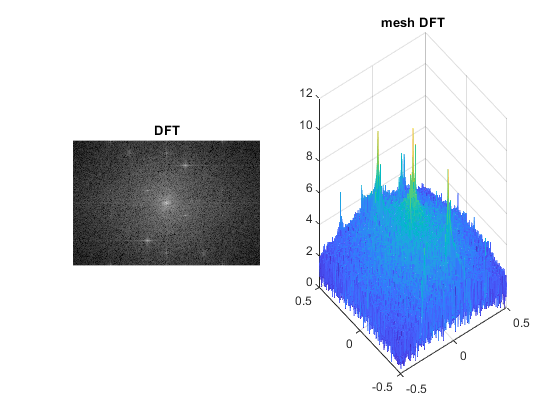


% Filtraggio 
Ifilt = I.*H;
i = real(ifft2(ifftshift(Ifilt)));

% Ricomposizione e conversione rgb
yhsi = cat(3,h,s,i);
y = hsi2rgb(yhsi);

% Visualizzazione
figure;
subplot(121); imshow(log(1+abs(I)),[]); title('DFT');
subplot(122); mesh(l,k,log(1+abs(I))); title('mesh DFT');

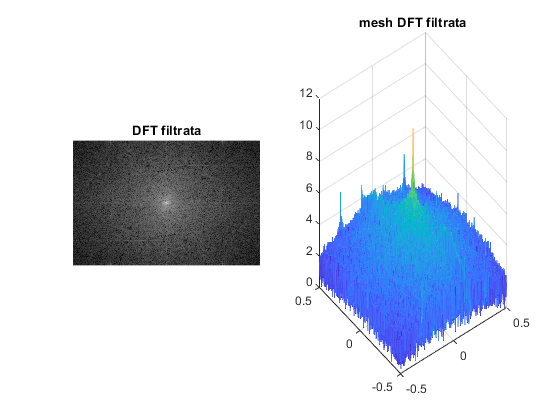

figure;
subplot(121); imshow(log(1+abs(Ifilt)),[]); title('DFT filtrata');
subplot(122); mesh(l,k,log(1+abs(Ifilt))); title('mesh DFT filtrata');

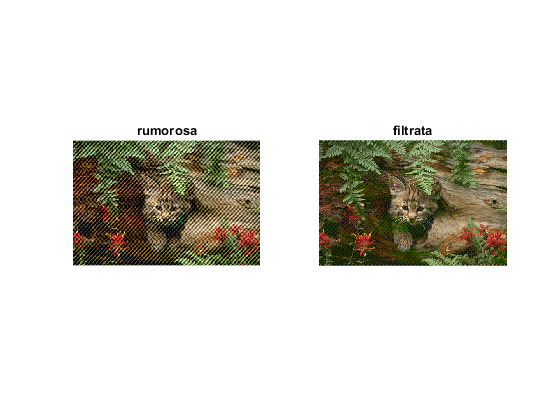

figure; 
subplot(121); imshow(x,[]); title('rumorosa');
subplot(122); imshow(y,[0 255]); title('filtrata');